# **                                    COURSE CODE: CME710 **

# **                COURSE: ADVANCED ENGINEERING MATHEMATICS **

#                   **                  NAME: MOSUDI ISIAKA**

#                **                  REG. NUMBER: PG823361 **

# **                DE****PT: TELECOMMUNICATION ENGINEERING **

# **                APPLICATION: MATLAB R2017a(LIVE SCRIPT) **

# **                                DATE: MARCH, 2018 **

**Modelling skydiver parachute[1] descent using Newton's second law of motion.**

**Compare numerical solutions for the differential equation, v' = 9.81 - v^2  ; given v(0) = 10, h = 0.05 and h = 0.1 Using Euler, Modified Euler and Runge-Kutta methods. **

**NB: Updated version available at:** [https://github.com/imosudi/matlabnewbie ](https://github.com/imosudi/matlabnewbie )

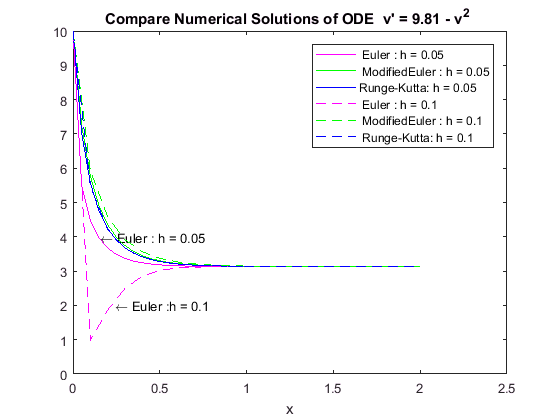

clear
t=0;v=10;        %% Declare Initial Conditions
t_final=2;      %% Assuming I am expected to stop iteration at x=800 minutes
t0 = t; v0 = v;

h=0.05;                                         %% Plot for step size, h=0.1
[t1,data1] = eulerm(t,v,h,t_final);            %% Euler method
[t2,data2] = eulermimproved(t,v,h,t_final);    %% Modified Euler method
[t3,data3] = rungek(t,v,h,t_final);            %% Runge-Kutta method

h=0.1;                                         %% Plot for step size, h=0.2
[t4,data4] = eulerm(t,v,h,t_final);            %% Euler method
[t5,data5] = eulermimproved(t,v,h,t_final);    %% Modified Euler method
[t6,data6] = rungek(t,v,h,t_final);            %% Runge-Kutta method

xspan = [t0 t_final];                          %% The Plot for exact solution
[t,v] = ode23(@(t,v) 9.81 - v^2 , xspan, v0);

subplot(2,2,[1 4]);
plot(t1,data1,'color', 'm') ;hold on;
text(0.13,4 ,' \leftarrow Euler : h = 0.05');   
plot(t2,data2,'color', 'g')
plot(t3,data3,'color', 'b')
plot(t4,data4,'m--'); text(0.22,2.0 ,' \leftarrow Euler :h = 0.1'); 
plot(t5,data5,'g--')
plot(t6,data6,'b--'); hold off;
titlestr = "Compare Numerical Solutions of ODE  v' = 9.81 - v^2 "; % + newline ; 
title(titlestr);xlabel('x');
legend(' Euler : h = 0.05', ' ModifiedEuler : h = 0.05', ...
    ...
     'Runge-Kutta: h = 0.05 ', ' Euler : h = 0.1', ...
     ...
     ' ModifiedEuler : h = 0.1', ' Runge-Kutta: h = 0.1 ', ...
     ...
      'Location','northeast') ;


subplot(2,2,[1 4]);

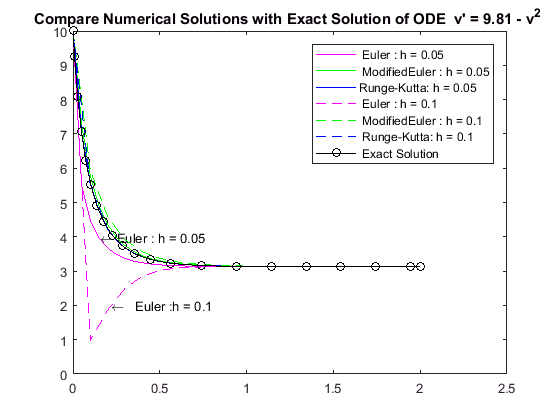

plot(t1,data1,'color', 'm') ;hold on;
text(0.13,4 ,' \leftarrow Euler : h = 0.05');   
plot(t2,data2,'color', 'g')
plot(t3,data3,'color', 'b')
plot(t4,data4,'m--'); text(0.22,2.0 ,'\leftarrow   Euler :h = 0.1'); 
plot(t5,data5,'g--')
plot(t6,data6,'b--')
plot(t,v, 'k-o')
titlestr = "Compare Numerical Solutions with Exact Solution of ODE " ...
    ...
    + " v' = 9.81 - v^2 "; %  + newline ; 
title(titlestr);
legend(' Euler : h = 0.05', ' ModifiedEuler : h = 0.05', ...
    ...
     'Runge-Kutta: h = 0.05 ', ' Euler : h = 0.1', ...
     ...
     ' ModifiedEuler : h = 0.1', ' Runge-Kutta: h = 0.1 ', ...
     ...
     ' Exact Solution', 'Location','northeast')

**Exact solution**

 v = derivs2(v0);

$$ode(t) = \frac{\partial }{\partial t}v\left(t\right)=\frac{981}{100}-{v\left(t\right)}^{2}$$

$$v = \frac{3\,\sqrt{109}\,\tanh\left(30\,\sqrt{109}\,\left(\frac{t}{100}+\frac{\sqrt{109}\,\mathrm{atanh}\left(\frac{100\,\sqrt{109}}{327}\right)}{3270}\right)\right)}{10}$$

**Runge-Kutta 4th Order**

function [t, data] = rungek(x,v,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
     t(1) = x; data(1,:) = v; %% store intial condition
    for i =1:Nsteps
        dv = derivs(x,v); k1 = h*dv;
        dv = derivs(x + h/2,v+k1/2); k2 = h*dv;
        dv = derivs(x + h/2,v+k2/2); k3 = h*dv;
        dv = derivs(x + h,v+k3); k4 = h*dv;
        k = (k1 + 2 * k2 + 2 * k3 + k4)/6;
        v = v + k; x = x + h;
        t(i+1) = x; data(i+1,:) = v ; 
    end
end

**Modified Euler Method**

function [t, data] = eulermimproved(x,v,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x; data(1,:) = v; %% store intial condition
    for i =1:Nsteps
        dv = derivs(x,v); k1 = h*dv;
        x = x + h;
        dv = derivs(x, v+k1); k2 = h*dv;
        v = v + (k1 + k2)./2;
        t(i+1) = x; data(i+1,:) = v ; 
   end
end

**Euler Method**

function [t, data] = eulerm(x,v,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x;data(1,:) = v;  %% store intial condition
    for i =1:Nsteps
        dv = derivs(x,v); v = v + h*dv;
        x = x + h;
        t(i+1) = x; data(i+1,:) = v ; 
    end
end

**Solution to the differential equation**

function v = derivs2(v0) 
    syms v(t)
    dv = derivs(t,v);

    ode = diff(v) == dv
    cond = v(0) == v0;
    v = dsolve(ode,cond)
end

**The differential equation**

function dv = derivs(t,v )
    dv = 9.81 - v^2 ;
end


**Conclusion:** 

Obviously from the graph Euler method as a solution to ODE produces irregular result, even at slight 

change in step size,h. Solution, v, of the ODE applying Euler method continues to deviate from the 

exact solution with increase in the independent variable, t. Whereas, the solutions of ODE using 

Modified Euler method and Runge-kutta method remain same, even, with the change in step size, h. 

Likewise, the two solutions agree with the exact solution, to a large extent, throughout the range of the 

independent variable, t. Therefore, both Modified Euler method and Runge-kutta method are better 

numerical solution of ODE but Euler method will produce less accurate results

**Reference:**

-  Advanced Engineering Mathematics (9th Edition, 2006) - Erwin Kreyszig